clc;
clear all;
close all;


% Initial parameters
f1 = 50;
fs = 10000;
T  = 0.2;
n = fs*T;
t = (0:n-1)/fs;
m = 30*2;
dt = 1/((fs/f1)*f1); %1/fs;
w = 2*pi*f1;

% x = (1*cos(2*pi*f1*t+(-1.488)))+((0.77)*cos(2*pi*3*f1*t+(1.560)))+((0.56)*cos(2*pi*5*f1*t+(-1.589)))+....
%     ((0.32)*cos(2*pi*7*f1*t+(1.545)))+((0.12)*cos(2*pi*9.46*f1*t+(-1.606)))+((0.06)*cos(2*pi*13*f1*t+(1.523)))+.....
%     ((0.06)*cos(2*pi*15.5*f1*t+(-1.632)))+((0.03)*cos(2*pi*17*f1*t+(1.4945)))+((0.03)*cos(2*pi*23*f1*t+(1.616)));

Considering this signal

x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t);
% x = cos(w*t) + 0.05*cos(0.6*w*t) + 0.02*cos(3*w*t);

tic


% x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t) + 0.05*cos(6.3*w*t)

% x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t) + 0.05*cos(6.3*w*t) + randn(size(t));
% x = x + 50 * rand(1, length(x));

### Henkel Matrix

Original Case of Hankel Matrix (this needs to be uncommented to run the original case)

% for k = 1:m
%     X(k,:) = x(k:(end-m+k));
% end
% X

The above matrix can also be generated by slicing the original Hankel matrix as follows

% X = hankel(x)
% X = X(1:m,1:end-m+1)



Below is thr prrof that both the generated matrix and sliced matrix from built-in function is same.

% a = X == X1
% sum(a, "all") == 60*1221 


From the above intuition, we can similarly slice and generate other matrices.

### Toeplitz matrix

% X = toeplitz(x,x)
% X = X(1:m,1:end-m+1)

### Circulant Matrix

%   X = gallery('circul' , x); 
% % Version 1
% X = X(1:end-m+1,1:m);
% X = X'

% Version 2
% X = X(1:m, 1:end-m+1)

## Circular shift - v1

We are shifting all the rows of i-th column i times in the upward direction. 

% a = repmat(x,60,1)
% for i=2:size(a,1)
%     a(:,i) = circshift(a(:,i),i-1);
% end
% X = a(:,1:end-m+1)

% a = repmat(x,60,1)
% for i=2:size(a,1)
%     a(i,:) = circshift(a(i,:)',i-1);
% end

Reverse of Henkel - Right side shift by 1 place.

Change of i and -i will change the directon of shift in the matrix

% for i = 1:m
%     X(i,:) = circshift(x,-i);
%     
% end
% % X = X(:,1:end-m+1)
% % X = X'
% X = X(:,1:end-m+1)

X = circ_toepl(x,m)

X =    -0.2612   -0.2053   -0.1479   -0.0892   -0.0298    0.0298    0.0892    0.1479    0.2053    0.2612    0.3155    0.3679    0.4187    0.4681    0.5164    0.5639    0.6109    0.6576    0.7042    0.7505    0.7964    0.8414    0.8847    0.9256    0.9632    0.9965    1.0245    1.0464    1.0614    1.0690    1.0690    1.0614    1.0464    1.0245    0.9965    0.9632    0.9256    0.8847    0.8414    0.7964    0.7505    0.7042    0.6576    0.6109    0.5639    0.5164    0.4681    0.4187    0.3679    0.3155
    1.0700   -0.2335   -0.1768   -0.1187   -0.0596    0.0000    0.0596    0.1187    0.1768    0.2335    0.2886    0.3419    0.3935    0.4436    0.4924    0.5402    0.5874    0.6343    0.6809    0.7274    0.7736    0.8190    0.8633    0.9055    0.9449    0.9804    1.0112    1.0363    1.0548    1.0662    1.0700    1.0662    1.0548    1.0363    1.0112    0.9804    0.9449    0.9055    0.8633    0.8190    0.7736    0.7274    0.6809    0.6343    0.5874    0.5402    0.4924    0.4436    0.3935    0

X = X(:,1:end-m+1)

X =    -0.2612   -0.2053   -0.1479   -0.0892   -0.0298    0.0298    0.0892    0.1479    0.2053    0.2612    0.3155    0.3679    0.4187    0.4681    0.5164    0.5639    0.6109    0.6576    0.7042    0.7505    0.7964    0.8414    0.8847    0.9256    0.9632    0.9965    1.0245    1.0464    1.0614    1.0690    1.0690    1.0614    1.0464    1.0245    0.9965    0.9632    0.9256    0.8847    0.8414    0.7964    0.7505    0.7042    0.6576    0.6109    0.5639    0.5164    0.4681    0.4187    0.3679    0.3155
    1.0700   -0.2335   -0.1768   -0.1187   -0.0596    0.0000    0.0596    0.1187    0.1768    0.2335    0.2886    0.3419    0.3935    0.4436    0.4924    0.5402    0.5874    0.6343    0.6809    0.7274    0.7736    0.8190    0.8633    0.9055    0.9449    0.9804    1.0112    1.0363    1.0548    1.0662    1.0700    1.0662    1.0548    1.0363    1.0112    0.9804    0.9449    0.9055    0.8633    0.8190    0.7736    0.7274    0.6809    0.6343    0.5874    0.5402    0.4924    0.4436    0.3935    0

### Time Shift

#### Row wise

% Xaug = X(1:end-1,:);
% Xaug2 = X(2:end,:);

#### Column wise (Original)

Xaug = X(:,1:end-1);
Xaug2 = X(:,2:end);

No changes in the code from here

r = m; % number of modes

[U,S,V] = svd(Xaug,'econ');
Xaug1 = Xaug';
beta = size(Xaug1,2)/size(Xaug1,1)  % aspect ratio of matrix

beta = 0.0309

sigma = diag(S);             % extract singular values
% optimal threshold tau
tau = optimal_SVHT_coef(beta,0)*median(sigma);  

rank_S = rank(S);
% figure
% semilogy(sigma,'k-o','LineWidth',1.2)
% hold on
% semilogy(sigma(sigma>tau),'ro','LineWidth',1.2)
% grid on


SD = sigma(sigma>tau);
r = size(SD,1);


U_r = U(:, 1:r);
S_r = S(1:r, 1:r);
V_r = V(:, 1:r);


%%% Changed inv to pinv
Atilde = U_r'*Xaug2*V_r*pinv(S_r);
[W,lambda] = eig(Atilde);
Omega = diag(log(diag(lambda)))/dt;
phi = Xaug2*V_r*pinv(S_r)*W;


b = phi\Xaug(:,1); % mode amplitude
% for k = 1:length(t)
%     xaugdmd(:,k) = phi*exp(Omega*t(k))*b;
% end

% % % % figure;plot(t,real(xaugdmd(1,:)),'linewidth',1.5);axis tight;grid on; hold on
% % % % plot(t,x1); 

Ext_fer = imag(diag(Omega./(2*pi)));
DMDfreqs = ((log(diag((lambda))))/(2*pi*dt));


DMDpower  = abs(b)*2/sqrt(m);
max(DMDpower)

ans = 1.0290

fest = abs(imag(DMDfreqs));
toc

Elapsed time is 0.367909 seconds.


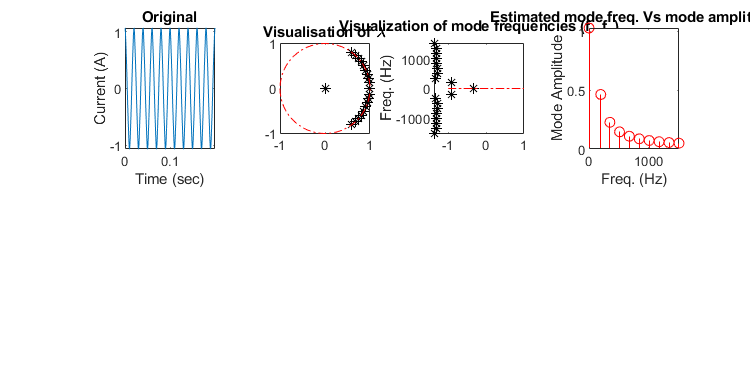


LW = 'LineWidth';

%% eigenvalue
figure('Position', [100 100 600 300]);
subplot(2,4,2);plot(lambda, 'k*');rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'r', 'LineStyle', '-.');axis(1.2*[-1 1 -1 1]);axis square;axis tight;title('Visualisation of \lambda')
subplot(2,4,3);plot(DMDfreqs, 'k*');rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'r', 'LineStyle', '-.');axis(200*[-1 1 -1 1]);axis square;ylabel('Freq. (Hz)');axis tight;title('Visualization of mode frequencies (f_u,f_v)')
subplot(2,4,4);
stem(fest,DMDpower,'r');xlabel('Freq. (Hz)');ylabel('Mode Amplitude');axis tight;title('Estimated mode freq. Vs mode amplitude')
% figure;stem(fest,DMDpower,'r');xlabel('Freq. (Hz)');ylabel('Mode Amplitude');axis tight;title('Estimated mode freq Vs amplitude')
            subplot(2,4,1);plot(t,x);axis tight;xlabel('Time (sec)');ylabel('Current (A)');axis tight;title('Original')

phase_ang = [];

function final = circ_toepl(data_matrix , iters)
for i = 1:iters
    b(i,:) = circshift(data_matrix,i-1);
    
end
for i = 1:size(b,2)
    c(:,i) = circshift(b(:,i),i);
end
final = c;
end
